% voltage controller loop
% v to duty transfer function of boost converter
Vin=60

Vin = 60

Vout=96

Vout = 96

R=23

R = 23

L=3.1e-3

L = 0.0031

r_l=0.01

r_l = 0.0100

C_out=440e-6

C_out = 4.4000e-04

r_c=0.1

r_c = 0.1000

D=0.6

D = 0.6000

w_z1=1/(r_c*C_out)

w_z1 = 2.2727e+04

T1=1/w_z1

T1 = 4.4000e-05

w_o=Vin/(Vout*sqrt(L*C_out))

w_o = 535.1467

fo=w_o/(2*pi)

fo = 85.1712

w_rhpzero=(R/L)*((Vin/Vout)^2)

w_rhpzero = 2.8982e+03

T2=1/w_rhpzero

T2 = 3.4504e-04

Q=w_o/((r_l/L)+(1/(C_out*(R+r_c))))

Q = 5.2666

M=(Vout)^2/Vin

M = 153.6000

T3=1/(w_o*Q)

T3 = 3.5481e-04

T4=1/(w_o^2)

T4 = 3.4918e-06

k1=M*(T1+T2)

k1 = 0.0598

k2=T1*T2*M

k2 = 2.3319e-06

%duty cycle to output voltage transfer function
G=tf([-k2 k1 M],[T4 T3 1])

G =
 
  -2.332e-06 s^2 + 0.05976 s + 153.6
  ----------------------------------
   3.492e-06 s^2 + 0.0003548 s + 1
 
Continuous-time transfer function.
Model Properties


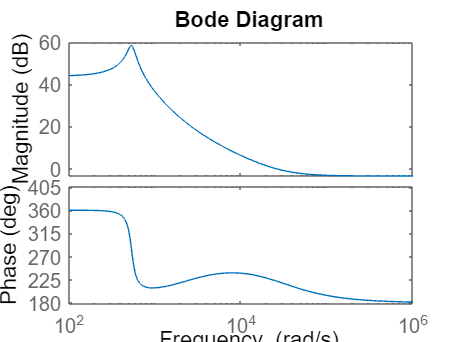

%% 

bode(G)

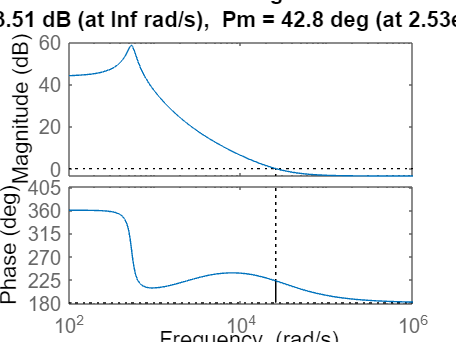

margin(G)

[Gm,Pm,Wcg,Wcp] = margin(G)

Gm = 1.4974

Pm = 42.7706

Wcg = Inf

Wcp = 2.5325e+04

%rlocus(G)
%controlSystemDesigner(G);
